## EMI Shielding

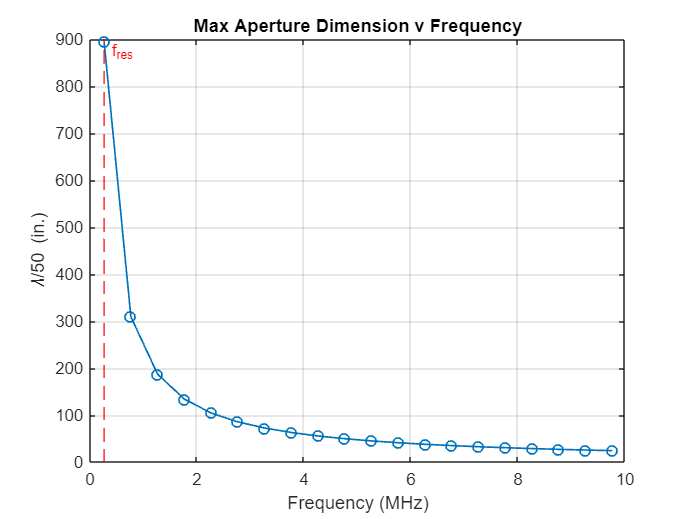


c = 299792458;      % speed of light, m/s
f_emi_max = SYSTEM.F_res_pri * 3;   % Max frequency of EMI to shield, Hz
MB.ENCLOSURE.lambda_min = c/f_emi_max;

% The rule applies to the longest dimension of any opening (slots, seams, vents)
MB.ENCLOSURE.d_max = MB.ENCLOSURE.lambda_min/50;    % meter

% Compute the maximum aperature dimension from the primary resonant
% frequency up to an arbitrary frequency
f = SYSTEM.F_res_pri:500e3:10e6;
% Ensure dimension does not exceed lamda/50 for each frequency step
d_max_m = (c./f)/50; % m

d_max_inch = d_max_m*39.3701

lineWidth = 1.0;
figure();
plot(f/1e6,d_max_inch,'-o',"LineWidth",lineWidth);
grid on;
title('Max Aperture Dimension v Frequency');
xlabel('Frequency (MHz)');
ylabel('\lambda/50 (in.)');
xline(SYSTEM.F_res_pri/1e6,'r--','f_{res}',"LabelOrientation","horizontal", "LineWidth",lineWidth);

## Shielding Effectiveness

[Source](https://resources.system-analysis.cadence.com/blog/msa2021-the-size-of-apertures-and-the-emi-shield-wavelength)

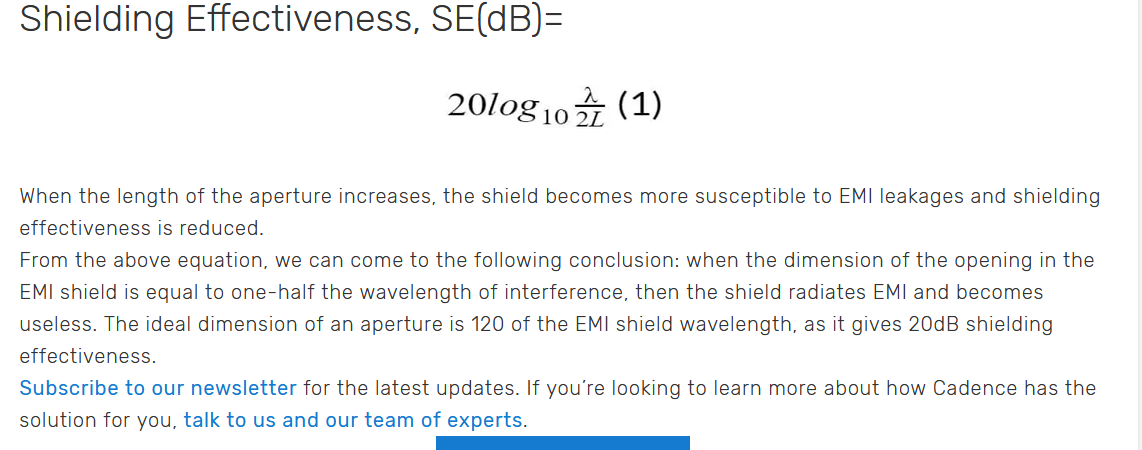

[Source](http://cdn.lairdtech.com/home/brandworld/files/EMI%20Rule-of-Thumb%20for%20Calculating%20Aperture%20Size%20Technical%20Note%20Download.pdf)

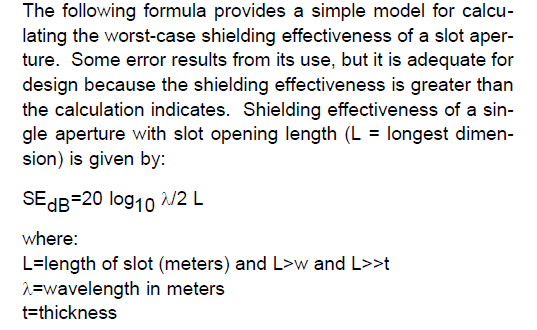

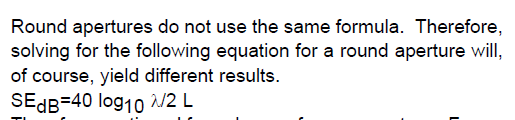

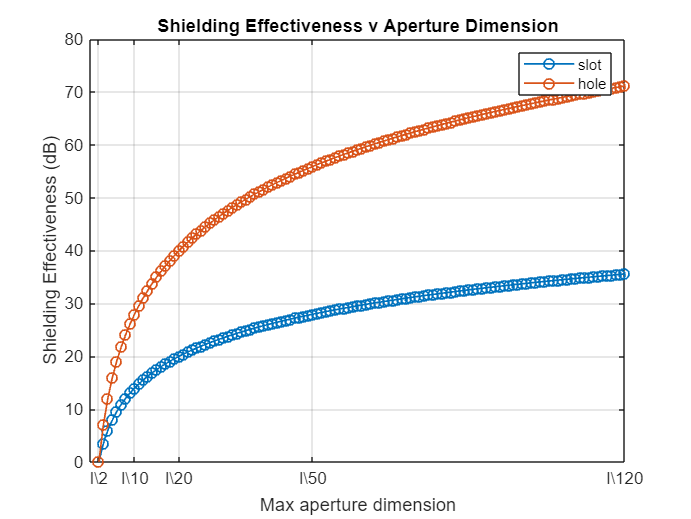

n = 2:1:120;

% Slot shielding effectiveness (dB)
se_dB_slot = 20 * log10(n/2);

% Round hold shielding effectiveness (dB)
se_dB_hole = 40 * log10(n/2);

lineWidth = 1.0;

% Compute the ticks and labels for x-axis
xticks_val = [2 10 20 50 120];
for i=1:length(xticks_val)
    xlabels(i) = sprintf("l\\%d",xticks_val(i));
end

figure();
plot(n,se_dB_slot,'-o', "LineWidth",lineWidth);
hold on;
plot(n,se_dB_hole,'-o', "LineWidth",lineWidth);
xlabel('Max aperture dimension');
ylabel('Shielding Effectiveness (dB)');
xticks(xticks_val);
xticklabels(xlabels);
legend("slot","hole");
title('Shielding Effectiveness v Aperture Dimension')
grid on;


% Attempt to get formatting on tick labels
%set(gca, 'TickLabelInterpreter', 'tex');
%ax = gca;
%ax.XAxis.TickLabelInterpreter = 'tex';
%exportgraphics(gca, 'my_plot.png', 'Resolution', 300);

## Run ADC DRC

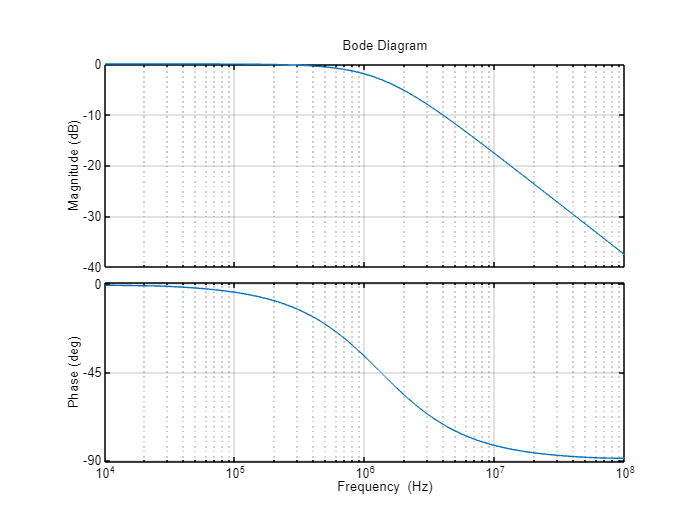



################ ADC Params BEGIN ##########################

ADC sampling frequency: 2.6400 MHz

Anti-aliasing filter R: 100.00 Ohm

Common mode anti-aliasing filter C: 1.2 nF

Common mode anti-aliasing filter cut-off frequency: 1315.33 kHz

Common mode anti-aliasing filter magnitude @ 264.00 kHz: -0.17 dB

Common mode anti-aliasing filter phase @ 264.00 kHz: -11.35 deg

Differential anti-aliasing filter cut-off frequency: 131.75 kHz

Differential anti-aliasing filter C: 6.0 nF

################ ADC Params END ##########################



ADC_DRC

## Show Results

fprintf("\n\n################ Motherboard Params BEGIN ##########################\n\n")



################ Motherboard Params BEGIN ##########################



fprintf("Max enclosure opening dimension: %0.2f mm (%0.2f in.)\n\n", MB.ENCLOSURE.d_max*1e3,  MB.ENCLOSURE.d_max*1e3*0.0393701);

Max enclosure opening dimension: 7570.52 mm (298.05 in.)



fprintf("################ Motherboard Params END ##########################\n\n")

################ Motherboard Params END ##########################

